## Beale function $f\left(x\right)={\left(1\ldotp 5-x+\mathrm{xy}\right)}^2 +{\left(2\ldotp 25-x+{\mathrm{xy}}^2 \right)}^2 +{\left(2\ldotp 625-x+{\mathrm{xy}}^3 \right)}^2$ con minimo nel punto $\left(3\ldotp 0,0\ldotp 5\right)$.

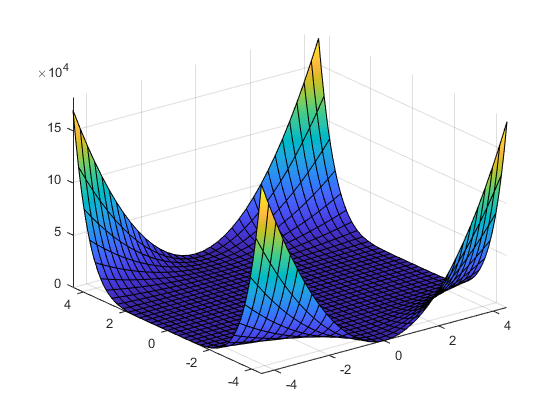

f_1= @(x) (1.5-x(1)+x(1)*x(2))^2 + (2.25-x(1)+x(1)*(x(2)^2))^2 + (2.625-x(1)+x(1)*(x(2)^3))^2;
nvars=2;
lb=[-4.5,-4.5];
ub=[4.5,4.5];

%plot
fsurf(@(x,y)(1.5-x+x*y)^2+(2.25-x+x*y^2)^2+(2.625-x+x*y^3)^2,[-4.5 4.5 -4.5 4.5])

%%ParticleSwarm%%
options = optimoptions('particleswarm','SwarmSize',100);
tic
[x,fval,exitflag,output]=particleswarm(f_1,nvars,lb,ub)

Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x =     3.0000    0.5000


fval = 1.3758e-10

exitflag = 1

output = struct with fields:
      rngstate: [1×1 struct]
    iterations: 59
     funccount: 1200
       message: 'Optimization ended: relative change in the objective value ↵over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.'


toc

Elapsed time is 0.109920 seconds.


Eseguendo l'algoritmo più volte, si nota che variando il numero di particelle, il minimo globale resta sostanzialmente invariato almeno fino alla terza cifra decimale, come anche il tempo di esecuzione. Cambia invece il numero di iterazioni, che, al variare delle particelle, resta confinato in un range di 40-70 iterazioni.

%%PatternSearch%%
options = optimoptions('patternsearch','MaxIterations',500);
x0=[2.8,0.3];
tic
[x,fval,exitflag,output]=patternsearch(f_1,x0,[],[],[],[],lb,ub,[],options)

Optimization terminated: mesh size less than options.MeshTolerance.


x =     2.9999    0.5000


fval = 7.9234e-10

exitflag = 1

output = struct with fields:
         function: @(x)(1.5-x(1)+x(1)*x(2))^2+(2.25-x(1)+x(1)*(x(2)^2))^2+(2.625-x(1)+x(1)*(x(2)^3))^2
      problemtype: 'boundconstraints'
       pollmethod: 'gpspositivebasis2n'
    maxconstraint: 0
     searchmethod: []
       iterations: 252
        funccount: 701
         meshsize: 9.5367e-07
         rngstate: [1×1 struct]
          message: 'Optimization terminated: mesh size less than options.MeshTolerance.'


toc

Elapsed time is 0.368739 seconds.


Pattern Search restituisce il valore del global minimum mediamente in 30 iterazioni. In particolare, si osserva che, quando il punto iniziale x0 è molto vicino al punto di minimo, il numero di iterazioni cresce notevolmente ( ad esempio con x0=(2.8,0.3) il numero di iterazioni risulta 252) insieme al tempo di esecuzione (passando da un decimo di secondo a tre decimi di secondo). Ciò è dovuto al fatto che l'algoritmo esplora una mesh di punti definiti sulla base di un set di direzioni sufficientemente ricco da garantire che si trovi una direzione di discesa, se ne esiste una, e quindi, partendo troppo vicini al global minimum tale direzione risulta più difficile da trovare.

%%FminSearch%%
x0=[0.7,2.8];
options = optimset('MaxFunEvals', 1000,'MaxIter', 1000);
tic
[x,fval,exitflag,output] = fminsearch(f_1,x0, options)

x =     3.0000    0.5000


fval = 2.8444e-10

exitflag = 1

output = struct with fields:
    iterations: 57
     funcCount: 108
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 ↵'


toc

Elapsed time is 0.054102 seconds.


Fmin Search, contrariamente al Pattern Search, quando il punto iniziale è molto lontano dal punto di minimo globale cercato, è necessario un numero di iterazioni ed un numero di valutazioni di funzione sempre maggiore. Il tempo di esecuzione resta invariato al variare del punto iniziale x0.

%%Algoritmi genetici%%
optionsga= optimoptions('ga', 'MaxGenerations', 500);
tic
[x,fval,exitflag,output] = ga(f_1, nvars, [],[],[],[],lb, ub, [],optionsga)

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


x =     3.0010    0.5002


fval = 1.7971e-07

exitflag = 1

output = struct with fields:
      problemtype: 'boundconstraints'
         rngstate: [1×1 struct]
      generations: 66
        funccount: 3350
          message: 'Optimization terminated: average change in the fitness value less than options.FunctionTolerance.'
    maxconstraint: 0


toc

Elapsed time is 0.297418 seconds.


clc

Si osserva che, quando il punto iniziale è sufficientemente vicino al minimo, l'algoritmo di ricerca del minimo che risulta essere più veloce ed efficiente è Fmin Search. Se, invece, non si è a conoscenza della posizione del punto di minimo l'algoritmo migliore, dal punto di vista di numero di iterazioni e tempo di esecuzione, risulta essere il Particle Swarm

## **Rosenbrock function** constrained to a disk $f\left(x,y\right)={\left(1-x\right)}^2 +100{\left(y-x^2 \right)}^2$ con minimo nel punto $\left(1,1\right)$.

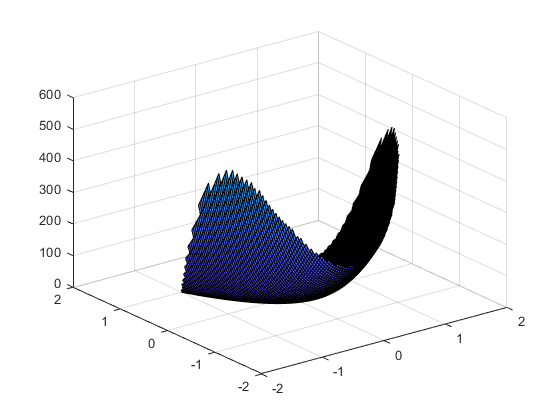

f_2=@(x) (1-x(1))^2 + 100*(x(2)-x(1)^2)^2;
nvars=2;
lb=[-1.5,-1.5];
ub=[1.5,1.5];

%plot
[xx,yy] = meshgrid(linspace(-1.5,1.5,100));
ff=(1-xx).^2+100*(yy-xx.^2).^2;
keepind = (xx.^2 + yy.^2) <= 2;
xx(~keepind) = NaN;
yy(~keepind) = NaN;
surf(xx,yy,ff);

%%PatternSearch%%
options = optimoptions('patternsearch','MaxIterations',500);
x0=[-1.5,-1.5];
tic
[x,fval,exitflag,output]=patternsearch(f_2,x0,[],[],[],[],lb,ub,@ellipsetilt,options)

Maximum number of function evaluations exceeded: increase options.MaxFunctionEvaluations.


x =     0.9397    0.8829


fval = 0.0036

exitflag = 0

output = struct with fields:
         function: @(x)(1-x(1))^2+100*(x(2)-x(1)^2)^2
      problemtype: 'nonlinearconstr'
       pollmethod: 'gpspositivebasis2n'
    maxconstraint: 0
     searchmethod: []
       iterations: 3
        funccount: 4000
         meshsize: 1.0000e-07
         rngstate: [1×1 struct]
          message: 'Maximum number of function evaluations exceeded: increase options.MaxFunctionEvaluations.'


toc

Elapsed time is 2.734157 seconds.


Per quanto riguarda l'esecuzione del Pattern Search non si osservano cambiamenti significativi nei tempi di esecuzione, nè nel numero di iterazioni, al variare del punto iniziale x0.

%%FminSearch%%
x0=[-1.5,-1.5];
tic
[x,fval,exitflag,output] = fminsearch(f_2,x0)

x =     1.0000    1.0000


fval = 6.5075e-10

exitflag = 1

output = struct with fields:
    iterations: 54
     funcCount: 105
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 ↵'


toc

Elapsed time is 0.048308 seconds.


Anche con Fmin Search al variare del punto iniziale non si osservano cambiamenti significativi nel minimo trovato o neltempo di esecuzione, fatta eccezione per un leggero aumento del numero di iterazioni necessarie quando il punto x0 è collocato sul bordo del dominio della funzione.

%%Algoritmi Genetici%
optionsga= optimoptions('ga', 'MaxGenerations', 500);
tic
[x,fval,exitflag,output] = ga(f_2, nvars, [],[],[],[],lb, ub,@ellipsetilt,optionsga)

Optimization terminated: average change in the fitness value less than options.FunctionTolerance
 and constraint violation is less than options.ConstraintTolerance.


x =     0.9948    0.9896


fval = 2.7582e-05

exitflag = 1

output = struct with fields:
      problemtype: 'nonlinearconstr'
         rngstate: [1×1 struct]
      generations: 5
        funccount: 13050
          message: 'Optimization terminated: average change in the fitness value less than options.FunctionTolerance↵ and constraint violation is less than options.ConstraintTolerance.'
    maxconstraint: 0


toc

Elapsed time is 2.637145 seconds.


clc

Si può concludere che l'algoritmo che meglio performa in termini di tempo di esecuzione e minimo trovato è Fmin Search.

## Gomez and Levy function (modified) $f\left(x,y\right)=4x^2 -2\ldotp 1x^4 +\frac{1}{3}x^6 +\mathrm{xy}-4y^2 +4y^4$ con minimo nel punto $\left(0\ldotp 08984201,-0\ldotp 71226564\right)$.

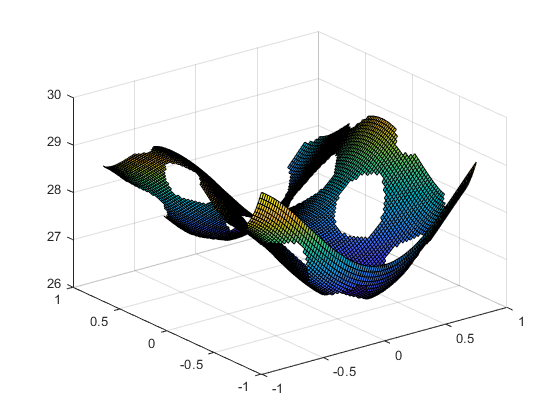

f_3= @(x)4*x(1)^2-2.1*x(1)^4+(1/3)*x(1)^6+x(1)*x(2)-4*x(2)^2+4*x(2)^4;
nvars=2;
A = [];
b = [];
Aeq = [];
beq = [];
lb = [-1,-1];
ub = [0.75,1];
x0 = [-0.75,0.5];

[xx,yy] = meshgrid(linspace(-1,0.75,100));
ff=4*xx.^2-2.1*xx.^4+(1/3)*xx.^6+xx*yy-4*yy.^2+4*yy.^4;
keepind = (-sin(4*pi.*xx) + 2*(sin(2*pi.*yy)).^2) <= 1.5;
xx(~keepind) = NaN;
yy(~keepind) = NaN;
surf(xx,yy,ff);

%%PatternSearch%%
nonlcon = @ellipsetilt3; %si veda la fine dello script
x0=[0.3,0.1];
tic
x = patternsearch(f_3,x0,A,b,Aeq,beq,lb,ub,nonlcon)

Optimization terminated: mesh size less than options.MeshTolerance
 and constraint violation is less than options.ConstraintTolerance.


x =     0.0898   -0.7127


toc

Elapsed time is 0.262784 seconds.


Per il Pattern Search si osserva che quando il punto iniziale x0 è molto lontano dal minimo globale, quast'ultimo non coincide col minimo trovato dall'algoritmo. Il tempo di esecuzione non manifesta cambiamenti significativi.

%Algoritmi genetici%%
rng default % For reproducibility
nonlcon = @ellipsecons;
tic
x = ga(f_3,nvars,A,b,Aeq,beq,lb,ub,nonlcon)

Optimization terminated: average change in the fitness value less than options.FunctionTolerance
 and constraint violation is less than options.ConstraintTolerance.


x =     0.0898   -0.7127


toc

Elapsed time is 2.631659 seconds.


clc

Si può osservare che il Pattern Search, quando il punto iniziale x0 è sufficientemente vicino al minimo globale, ha un tempo di esecuzione nettamente inferiore rispetto agli algoritmi genetici.

## Easom function $f\left(x\right)=-\cos \left(x\right)\cos \left(y\right)e^{-\left\lbrack {\left(x-\pi \right)}^2 +{\left(y-\pi \right)}^2 \right\rbrack }$ con minimo globale in $\left(\pi ,\pi \right)$.

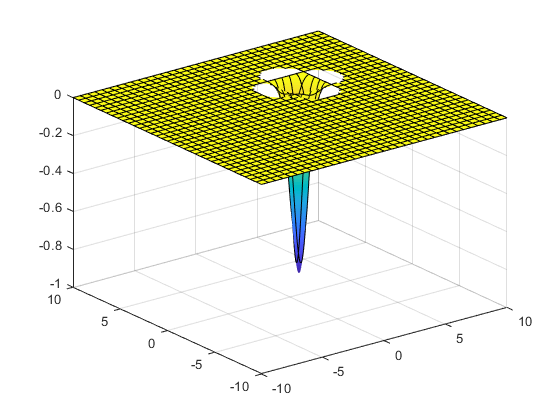

f_4 = @(x)-cos(x(1))*cos(x(2))*exp(-(((x(1)-pi)^2+(x(2)-pi)^2)));
nvars=2;
A=[];
b=[];
Aeq=[];
beq=[];
lb=[-100,-100];
ub=[100,100];
nonlcon=[];

%plot
fsurf(@(x,y)(-cos(x)*cos(y)*exp(-(((x-pi)^2+(y-pi)^2)))),[-10 10 -10 10])

%%ParticleSwarm%%
rng default
options = optimoptions('particleswarm','SwarmSize',200);
tic
[x,fval,exitflag,output] = particleswarm(f_4,nvars,lb,ub)

Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x =     3.1416    3.1416


fval = -1.0000

exitflag = 1

output = struct with fields:
      rngstate: [1×1 struct]
    iterations: 80
     funccount: 1620
       message: 'Optimization ended: relative change in the objective value ↵over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.'


toc

Elapsed time is 0.114980 seconds.


Particle Swarm retituisce il corretto valore del global minimum in 80 iterazioni, con tempo di esecuzione sostanzialmente invariato, indipendentemente dal numero di particelle.

%%PatternSearch%%
options = optimoptions('patternsearch','MeshTolerance',1e-4);
x0=[-10,10];
tic
[x,fval,exitflag,output] = patternsearch(f_4,x0,A,b,Aeq,beq,lb,ub,nonlcon,options)

Optimization terminated: mesh size less than options.MeshTolerance.


x =     3.1406    3.1406


fval = -1.0000

exitflag = 1

output = struct with fields:
         function: @(x)-cos(x(1))*cos(x(2))*exp(-(((x(1)-pi)^2+(x(2)-pi)^2)))
      problemtype: 'boundconstraints'
       pollmethod: 'gpspositivebasis2n'
    maxconstraint: 0
     searchmethod: []
       iterations: 44
        funccount: 149
         meshsize: 6.1035e-05
         rngstate: [1×1 struct]
          message: 'Optimization terminated: mesh size less than options.MeshTolerance.'


toc

Elapsed time is 0.107929 seconds.


Pattern Search restituisce un valore che coincide con il GlobalMinimum (in 30 iterazioni) se si parte da x0 molto vicino al punto di minimo altrimenti o non si sposta (ad esempio con x0=[30,30]) o non raggiunge il minimo (x0=[1,1]) in quanto l'algoritmo esplora una mesh di punti definiti sulla base si un set di direzioni sufficientemente ricco da garantire che si trovi una direzione di discesa se ne esiste una, quindi partendo lontano tale direzione non viene trovata e non ci si sposta dal punto iniziale.

%%FminSearch%% -- nelle opzioni non ce la possibilitÃ di mettere
%%l'intervallo di x e y ma l'algoritmo termina comunque
%fun=@(x)-cos(x(1))*cos(x(2))*exp(-((x(1)-pi)^2+(x(2)-pi)^2));
x0=[10,10];
tic
[x,fval,exitflag,output] = fminsearch(f_4,x0)

x =     3.1416    3.1416


fval = -1.0000

exitflag = 1

output = struct with fields:
    iterations: 41
     funcCount: 77
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 ↵'


toc

Elapsed time is 0.059818 seconds.


Fmin Search restituisce un valore che coincide con il global minimum sotto le stesse condizioni del Pattern Search ( ad esempio scegliendo x0=(10,10)).

%%Algoritmi Genetici%%
lb=[-100,-100];
ub=[100,100];
tic
[x,fval,exitflag,output] = ga(f_4,nvars,A,b,Aeq,beq,lb,ub)

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


x =     3.1416    3.1416


fval = -1.0000

exitflag = 1

output = struct with fields:
      problemtype: 'boundconstraints'
         rngstate: [1×1 struct]
      generations: 86
        funccount: 4350
          message: 'Optimization terminated: average change in the fitness value less than options.FunctionTolerance.'
    maxconstraint: 0


toc

Elapsed time is 0.368277 seconds.


Si può concludere che nel caso in cui non si conosca la posizione esatta o approssimativa del punto di global minimum, è conveniente usare gli algoritmi genetici. In alternativa, gli altri due metodi, scegliendo un x0 vicino al punto di minimo, risultano sostanzialmente equivalenti.